vid = VideoReader('ACM_2716_cylinder_water_tunneltrim_3.MP4');
frames = vid.NumFrames;
inten1 = zeros(1,frames);
inten2 = zeros(1,frames);
inten3 = zeros(1,frames);
for img_num = 1:frames
    b=read(vid,img_num);
    x = [2260 1930 1580];
    y = [1397 1397 1397];
    g = impixel(rgb2gray(b),x,y);
    inten1(img_num) = g(1,1);
    inten2(img_num) = g(2,1);
    inten3(img_num) = g(3,1);
end

corrcoff1 = zeros(1,frames);
corrcoff2 = zeros(1,frames);
corrcoff3 = zeros(1,frames);
mul = 0;
inten1flu = inten1 - mean(inten1);
inten2flu = inten2 - mean(inten2);
inten3flu = inten3 - mean(inten3);
rmsq1 = (rms(inten1flu))^2;
rmsq2 = (rms(inten1flu)*rms(inten2flu));
rmsq3 = (rms(inten1flu)*rms(inten3flu));

for dt = 0:frames-1
    mul1 = 0;
    mul2 = 0;
    mul3 = 0;
    for t = 1:frames-dt
        mul1 = mul1 + (inten1flu(1,t)*inten1flu(1,(t+dt)));
        mul2 = mul2 + (inten1flu(1,t)*inten2flu(1,(t+dt)));
        mul3 = mul3 + (inten1flu(1,t)*inten3flu(1,(t+dt)));
    end
    corrcoff1(dt+1) = (mul1/frames)./rmsq1;
    corrcoff2(dt+1) = (mul2/frames)./rmsq2;
    corrcoff3(dt+1) = (mul3/frames)./rmsq3;
end

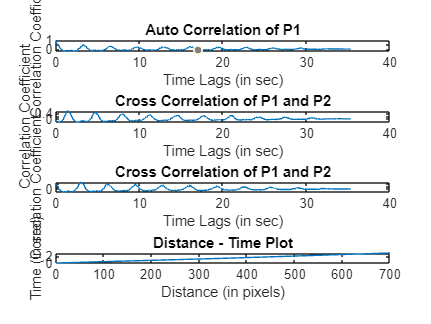

subplot(4,1,1)
x = 0:frames-1;
plot(x./vid.FrameRate,corrcoff1)
title("Auto Correlation of P1");
xlabel("Time Lags (in sec)");
ylabel("Correlation Coefficient");
subplot(4,1,2)
x = 0:frames-1;
plot(x./vid.FrameRate,corrcoff2)
title("Cross Correlation of P1 and P2");
xlabel("Time Lags (in sec)");
ylabel("Correlation Coefficient");
subplot(4,1,3)
x = 0:frames-1;
plot(x./vid.FrameRate,corrcoff3)
title("Cross Correlation of P1 and P2");
xlabel("Time Lags (in sec)");
ylabel("Correlation Coefficient");
deltat1 = (find(corrcoff1 == max(corrcoff1))-1)/vid.FrameRate;
deltat2 = (find(corrcoff2 == max(corrcoff2))-1)/vid.FrameRate;
deltat3 = (find(corrcoff3 == max(corrcoff3))-1)/vid.FrameRate;
subplot(4,1,4)
a = plot([0 350 700], [deltat1 deltat2 deltat3]);
title("Distance - Time Plot");
xlabel("Distance (in pixels)");
ylabel("Time (in sec)");

convvel = (max(a.XData)-min(a.XData))/(max(a.YData)-min(a.YData))

convvel = 233.1002